clear all


*Rewrite this intu a class, and make an instance of it a property of ship!*

## Define contour of the doc

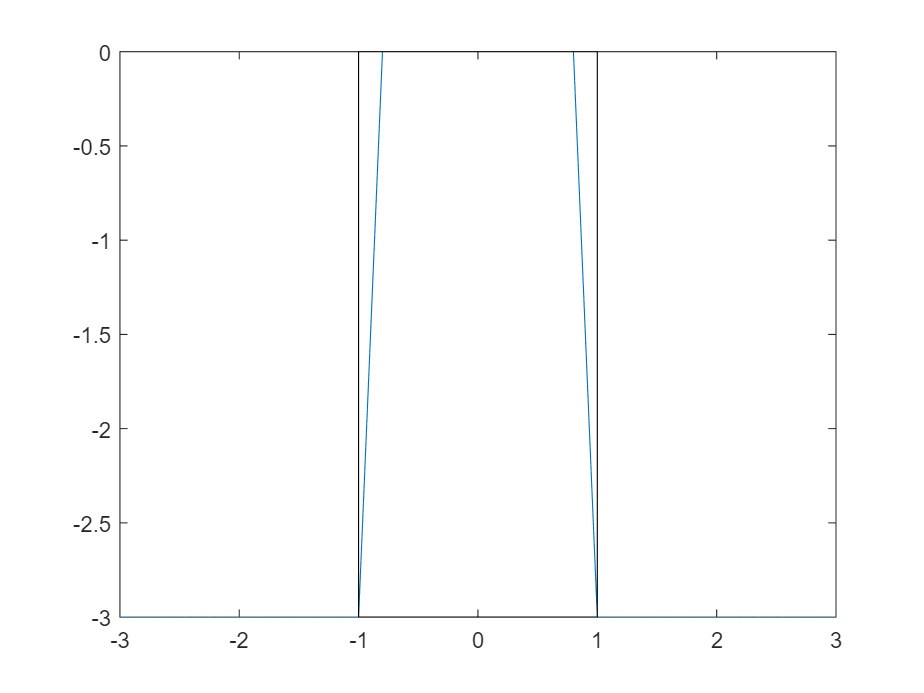



waypoint = [0, 0]'; 

cx_doc = waypoint(1); 
cy_doc = waypoint(2); 

d = 3; %depth [m]
w = 1; %width [m] 
w_toll = 0.9; 
s = 10e-3; %sharpness

sig = @(x)1/(1+exp(-x)); %sigmoid function

x_plot= -3:0.1:3;
f = zeros(1, length(cy_doc)); 

for i =1:length(x_plot)
   
    f(i, :) = cy_doc-d + d*(sig((x_plot(i)+w_toll-cx_doc)/s) - sig((x_plot(i)-w_toll-cx_doc)/s)); 
end

plot(x_plot, f); hold on; 

% Define the position, width, and height of the rectangle
width = w;
hight= d;
x_doc = cx_doc -width;
y_doc = cy_doc -d; 


% Draw the rectangle
rectangle('Position', [x_doc y_doc width*2 hight]);
hold off; 

We see in the lower corners the allowed area is 0.1 m to large. In the upper corners the allowed area is 0.1 m to little. This is with s = 10e-3

## Plot h~(extremal points)

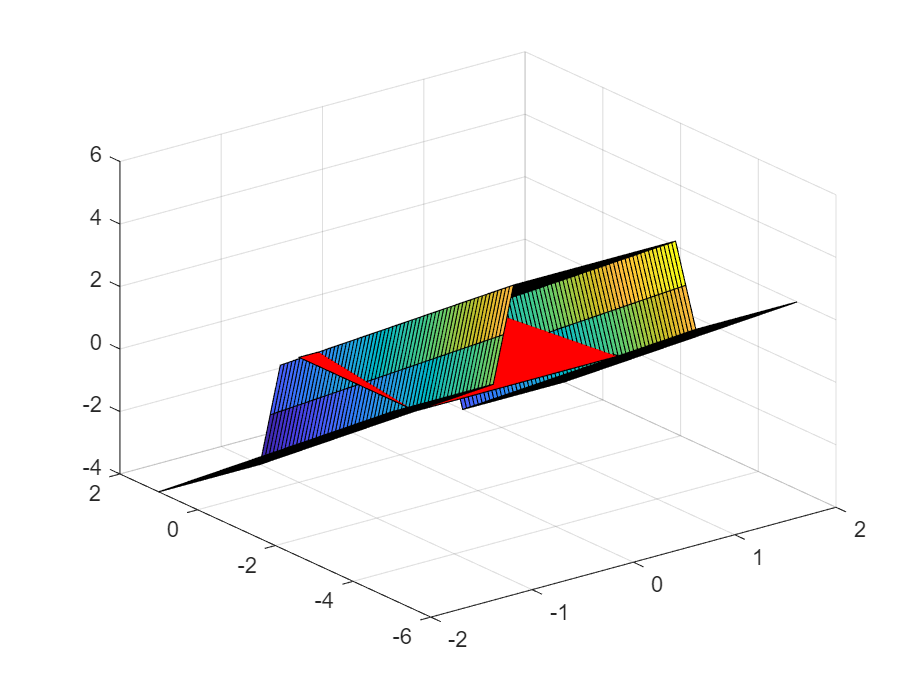



x_test = -2:0.1:2; 
y_test = -5:0.1:1; 

[X, Y] = meshgrid(x_test, y_test); 

doc =@(x) cy_doc-d + d*(sig((x+w_toll-cx_doc)/s) - sig((x-w_toll-cx_doc)/s)); 

DOC = zeros(size(X)); 

for r = 1:size(X, 1)
    for c = 1:size(X,2)
        DOC(r, c) = doc(X(r,c)); 
    end
end

Z = DOC - Y; 

surf(X,Y,Z)

hold on

rect_x = [x_doc, x_doc, x_doc + width*2, x_doc + width*2]; 
rect_y = [y_doc, y_doc + hight, y_doc + hight, y_doc]; 
rect_z = [1, 1, 1, 1]*(0);

patch(rect_x, rect_y, rect_z, 'r')

## Defining control barrier functions h_i(eta)


%The functio above dfines the aera where part of the vehicle can be. Now ltes maps this to functions of $\eta = [x_cg, y_cg, psi]$.

% The extremal points are defined as belov. If these 4 points are within
% the safe set, the entire boat, is within the safe set.
% IN this configuration we have eta(3) = psi = pi/2.

%    x1 ---------x2
%    |           |
%    |           |
%    |     *(x_cg, y_cg)  
%    |           |
%    |           |
%    x4----------x3

eta_test_1= [0; 1; 0] % x and psi are good, while y has gone too far

eta_test_1 =      0
     1
     0


h_1 = cbf_i(@doc, eta_test_1, 1)

eta_ext =    -2.5000
    2.5000


Unrecognized function or variable 'cy_doc'.

Error in viz_h>@(x)cy_doc-d+d*(sig((x+w_toll-cx_doc)/s)-sig((x-w_toll-cx_doc)/s)) (line 91)
    doc =@(x) cy_doc-d + d*(sig((x+w_toll-cx_doc)/s) - sig((x-w_toll-cx_doc)/s)); 

Error in viz_h>cbf_i (line 94)
    h_i = eta

eta_test_2 = [0; 0; 0]; % should be zero
h_1 = cbf_i(eta_test_2, 1)
eta_test_3 = [0; -1; 0]; % x, y, and psi are good.
h_1 = cbf_i(eta_test_2, 1)

function h_i = cbf_i(f, eta, i)
    sig = @(x)1/(1+exp(-x));
    doc =@(x) cy_doc-d + d*(sig((x+w_toll-cx_doc)/s) - sig((x-w_toll-cx_doc)/s)); 

    eta_ext = extremal_points(eta, i)
    h_i = eta_ext(2) - doc(eta_ext(1)) 
end

function eta_ext = extremal_points(eta, i)
    % let i be the number of the corner you want to compute the extrimal
    % point of. 

    length_boat = 2.5; 
    width_boat = 1.5; 
    
    d = sqrt(length_boat^2 + width_boat^2); 
    theta2 = atan((length_boat/2)/(width_boat/2)); 
    theta1 = theta2 + pi/2;
    theta4 = theta2 + pi; 
    theta3 = theta4 - pi/2;

    theta = [theta1; theta2; theta3; theta4]; 

    x_ext = eta(1) + d*cos(eta(3) + theta(i)); 
    y_ext = eta(2) + d*sin(eta(3) + theta(i)); 

    eta_ext = [x_ext; y_ext]; 
  
end